
clear; clc; close all;

run('C:\Users\Bruger\AppData\Roaming\MathWorks\MATLAB Add-Ons\Collections\vlfeat-0.9.21\toolbox\vl_setup.m');
%% Configuration
archivePath = 'C:\Users\Bruger\Desktop\DSP\project_AT_dataset\archive'; % Path to your ATT Face database
numPeopleToUse = 10; % Limit to 10 people 

% Load the pre-trained PCA and GMM models
fprintf('Loading pre-trained PCA and GMM models...\n');

Loading pre-trained PCA and GMM models...


load('surf_pca_model_AT.mat', 'surfPCA');
load('fisher_gmm_model_AT.mat', 'fisherGMM');
fprintf('Models loaded successfully.\n');

Models loaded successfully.



% Get dimensions from loaded models
reducedFeatureDimension = size(surfPCA.pcaCoeff, 2);
numGMMComponents = fisherGMM.GMModel.NumComponents;

% Fisher Vector dimension calculation
fisherVectorDimension = 2 * numGMMComponents * reducedFeatureDimension;
fprintf('Fisher Vector dimension: %d\n', fisherVectorDimension);

Fisher Vector dimension: 8192



% Helper function for Dense SIFT and Fisher Vector Encoding
function fisherVector = extractAndEncodeFV(img, pcaCoeff, gmmModel)
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    img = single(img); % VLFeat functions often prefer single precision and img input to dsift

    % Parameters for Dense SIFT: 'size' is the bin size, 'step' is the stride
    [locations, features] = vl_dsift(img, 'size', 8, 'step', 4);

    % Transpose to be NxD (N descriptors, D dimensions)
    features = features';
    features = single(features);

    featuresReduced = features * pcaCoeff;

    % Get the feature dimension (D) and number of GMM components (K)
    D = size(featuresReduced, 2); 
    K = gmmModel.NumComponents;  

    gmmSigmaForFisher = reshape(gmmModel.Sigma, D, K); % Reshape to D rows, K columns

    % Ensure all inputs to vl_fisher are single precision
    gmmMuForFisher = single(gmmModel.mu);
    gmmPriorsForFisher = single(gmmModel.ComponentProportion);
    
    % The vl_fisher function expects COVARIANCES to be D x K for diagonal covariances.
    fisherVector = vl_fisher(single(featuresReduced'), gmmMuForFisher, gmmSigmaForFisher, gmmPriorsForFisher);

    % Transpose the result back to a row vector for consistent storage
    fisherVector = fisherVector';
end


%% 1. Load Image information from ATT Face database
faceDatabase = imageDatastore(archivePath, ...
    'IncludeSubfolders', true, ... % Allow searching in subfolders
    'LabelSource', 'foldernames'); % Assign labels on images based on the folders


allUniqueLabels = unique(faceDatabase.Labels);% Get unique labels 
allUniqueLabels = sort(allUniqueLabels); % Sort for consistent selection

% Ensure we don't try to use more people than available
if numPeopleToUse > numel(allUniqueLabels)
    actualNumPeople = numel(allUniqueLabels);
else
    actualNumPeople = numPeopleToUse;
end

% Select the labels for the first 'actualNumPeople' individuals
selectedLabels = allUniqueLabels(1:actualNumPeople);

% Create a new imageDatastore containing only images from the selected people
filteredFaceDatabase = subset(faceDatabase, ismember(faceDatabase.Labels, selectedLabels));

fprintf('Processing images for %d people.\n', actualNumPeople);

Processing images for 10 people.


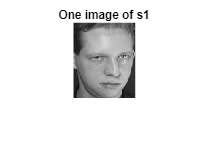


labels = filteredFaceDatabase.Labels; % Get all labels from the filtered set

figure(1);
% Find the first person's label in the selected set for display purposes
firstSelectedLabel = selectedLabels(1); 

if ismember(firstSelectedLabel, labels)
    image_folder = find(labels == firstSelectedLabel);
    if ~isempty(image_folder)
        imshow(imread(filteredFaceDatabase.Files{image_folder(2)})); % Display 2nd image from this person
        title(['One image of ' char(firstSelectedLabel)]);
    else
        title([char(firstSelectedLabel) ' not available in filtered set']);
    end
else
    title([char(firstSelectedLabel) ' not in selected people for display']);
end

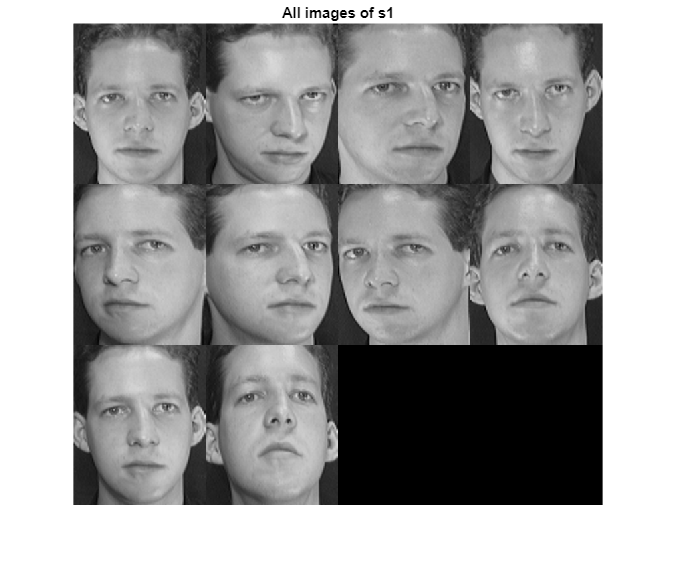



figure(2);
if ismember(firstSelectedLabel, labels)
    montage(filteredFaceDatabase.Files(labels==firstSelectedLabel)); % Display all images from this person
    title(['All images of ' char(firstSelectedLabel)]);
else
    title([char(firstSelectedLabel) ' not in selected people for display']);
end



%% 2. Splitting database into training and test sets (from the filtered database)
[trainingSet, testSet] = splitEachLabel(filteredFaceDatabase, 0.8, 0.2);

%% 3. Extracting Fisher Vector features from all training images
fprintf('Extracting Fisher Vector features from training set (%d images)...\n', numel(trainingSet.Files));

Extracting Fisher Vector features from training set (80 images)...


trainingFeatures = zeros(numel(trainingSet.Files), fisherVectorDimension); 
trainingLabels = cell(numel(trainingSet.Files), 1);   

featureCount = 1;
% Go through the unique labels of the *trainingSet* 
uniqueTrainingLabels = unique(trainingSet.Labels); 
for i = 1:numel(uniqueTrainingLabels) % loops through subfolders (persons)
    currentPersonLabel = uniqueTrainingLabels(i);
    subds = subset(trainingSet, trainingSet.Labels == currentPersonLabel); 
    
    for j = 1:numel(subds.Files) % loops through images within current person's folder
        img = read(subds);
        
        % Extract and Encode Fisher Vector
        trainingFeatures(featureCount, :) = extractAndEncodeFV(img, surfPCA.pcaCoeff, fisherGMM.GMModel);
        
        trainingLabels{featureCount} = char(currentPersonLabel);
        featureCount = featureCount + 1;
        
        if mod(featureCount-1, 50) == 0 || featureCount-1 == numel(trainingSet.Files)
            fprintf('  Processed %d/%d training images.\n', featureCount-1, numel(trainingSet.Files));
        end
    end
end

  Processed 50/80 training images.
  Processed 80/80 training images.


fprintf('Finished extracting training features.\n');

Finished extracting training features.



%% 4. Creating a classifier
fprintf('Training ECOC classifier...\n');

Training ECOC classifier...


faceClassifier = fitcecoc(trainingFeatures, categorical(trainingLabels));
fprintf('Classifier training complete.\n');

Classifier training complete.


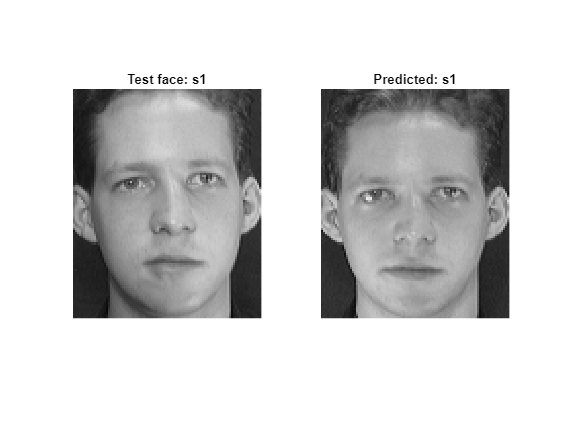


%% 5. Test Images from Test set
uniqueTestLabels = unique(testSet.Labels); % Get all unique person labels (will be from the number selected)

% Test the first person in test set (among the number selected)
person_lab_idx = 1;
personToTest = uniqueTestLabels(person_lab_idx);

des_sub = subset(testSet, testSet.Labels == personToTest);
desiredImage = read(des_sub); % Get test image

% Extract Fisher Vector features for the desired test image
desiredFeatures = extractAndEncodeFV(desiredImage, surfPCA.pcaCoeff, fisherGMM.GMModel);

% Predict the match based on the classifier
predLabel = predict(faceClassifier, desiredFeatures);

% Display results
figure;
subplot(1,2,1); imshow(desiredImage); title(['Test face: ' char(personToTest)]);
subplot(1,2,2);
% Find a matching image from the training set based on predicted label
matchedTrainImages = subset(trainingSet, trainingSet.Labels == predLabel);
if numel(matchedTrainImages.Files) > 0
    % Display the first image from the predicted label's training set
    imshow(read(matchedTrainImages));
else
    text(0.5, 0.5, 'No training image for predicted label.', 'HorizontalAlignment', 'center', 'Color', 'red');
end
title(['Predicted: ' char(predLabel)]);


%% 6. Test for 5 different people
fprintf('\nTesting classifier on 5 different people...\n');


Testing classifier on 5 different people...


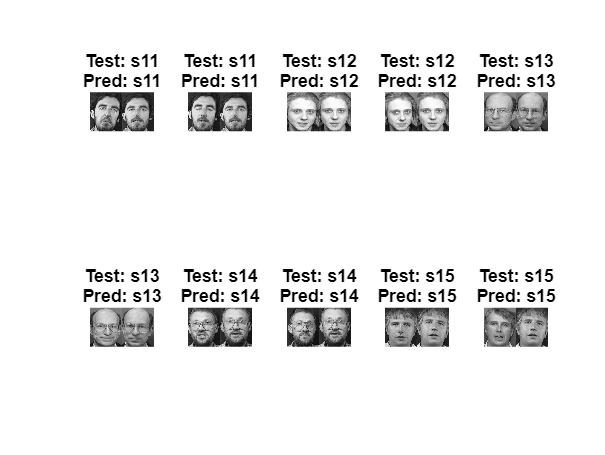

  Testing for person: s11
  Testing for person: s12
  Testing for person: s13
  Testing for person: s14
  Testing for person: s15


figure;
% Adjust this range to pick specific people from your selected 10 for display
peopleRangeToDisplay = 3:min(7, numel(uniqueTestLabels));


for rangeIdx = 1:numel(peopleRangeToDisplay)  % Loop through the chosen range
    personIdx = peopleRangeToDisplay(rangeIdx);
    currentLabel = uniqueTestLabels(personIdx);
    
    % Get all test images for this person
    personTestSet = subset(testSet, testSet.Labels == currentLabel);
    reset(personTestSet); % Reset the datastore to read from the beginning
    
    fprintf('  Testing for person: %s\n', char(currentLabel));
    
    % Test first 2 images per person
    for imgIdx = 1:min(2, numel(personTestSet.Files))
        queryImage = read(personTestSet);
        
        % Extract Fisher Vector features for the query image
        queryFeatures = extractAndEncodeFV(queryImage, surfPCA.pcaCoeff, fisherGMM.GMModel);
        
        % Predict the label
        predLabel = predict(faceClassifier, queryFeatures);
        
        % Find a matching training image for display
        trainMatch = subset(trainingSet, trainingSet.Labels == predLabel);
        matchedImage = [];
        if numel(trainMatch.Files) > 0
            reset(trainMatch);
            matchedImage = read(trainMatch); % Get the first image from the matched training set
        end
        
        % Display results
        subplot(2, 5, (rangeIdx-1)*2 + imgIdx);
        if ~isempty(matchedImage)
            imshowpair(queryImage, matchedImage, 'montage');
        else
            imshow(queryImage);
            text(0.5, 0.5, 'No matching training image', 'HorizontalAlignment', 'center', 'Color', 'red');
        end
        title(sprintf('Test: %s\nPred: %s', char(currentLabel), char(predLabel)));
    end
end

fprintf('Facial recognition testing complete.\n');

Facial recognition testing complete.
